**Heat equation**


$$\partial_t u - a\,\partial_{xx} u=f$$


% We solve the heat equation with Dirichlet Boundary conditions in 1D
% we want to solve $\partial_t u - \partial_{xx} u = 0.$
clc; clear all;

% Define the spatial and temporal domains 
geom.xL=0; geom.xR=2*pi;
T_end = 1;
PDE.a = 0.5; %diffusion coefficient
PDE.uL = 0.; % Dirichlet boundary values
PDE.uR = 0.; 

geom.Nx = 30;
Nt = 30;
geom.x = linspace(geom.xL, geom.xR, geom.Nx); % Spatial domain
geom.dx = geom.x(2)-geom.x(1);
t = linspace(0, T_end, Nt); % Temporal domain
dt = t(2)-t(1);
u = zeros(length(t),length(geom.x)); % Initialize solution matrix

u_exact = @(t,x) exp(-t)*sin(x);

Then, we introduce the discretization with finite differences and implicit Euler.

`Spatial discretization`


$$(\partial_{xx}u)_i  =- \frac{u_{i+1}-2u_i+u_{i-1}}{\Delta x^2}$$


so that the discrete problem becomes

$\partial_t \mathbf{u} = -D_2 \mathbf{u} $.

`Implicit Euler`


$$\frac{u^{n}_i-u^{n-1}_i}{\Delta t} - \frac{u_{i+1}^n-2u_i^n+u_{i-1}^n}{\Delta x^2}=0 
\Longleftrightarrow u^{n}_i-\frac{\Delta t}{\Delta x^2}(u_{i+1}^n-2u_i^n+u_{i-1}^n) = u^{n-1}_i$$


`Linear systems with matrix`

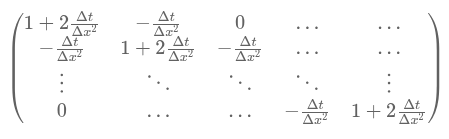

e = ones(geom.Nx,1);
D2 = spdiags([e,-2*e,e],-1:1,geom.Nx,geom.Nx);

A = speye(geom.Nx) -dt/geom.dx^2*D2;

% apply Dirichlet BC on matrix
A(1,:)=0;
A(1,1)=1;

A(geom.Nx,:)=0;
A(geom.Nx,geom.Nx)=1;


u(1,:)= sin(geom.x); 
% u(1,:)=  1*(geom.x<5).*(geom.x>3); %;

for it=2:Nt
    rhs = u(it-1,:)';
    rhs(1)=PDE.uL;
    rhs(geom.Nx)=PDE.uR;
    u(it,:) = A \rhs; % Solve the linear system for the next time step
end

Now, let's plot the solution and the exact one for comparison.


figure()
plot(geom.x, u(length(t),:),"DisplayName","approx");
hold on;
plot(geom.x, u_exact(t(end),geom.x),"DisplayName","exact")
plot(geom.x, u_exact(t(1),geom.x),"DisplayName","initial")
legend()

% compute the L2 relative error
err = norm(u(Nt,:)- u_exact(t(end),geom.x))/norm( u_exact(t(end),geom.x));
fprintf("The L2 relative error is %1.3e",err);

Change Nx and Nt and see what happens to the error! Try to change also the initial conditions.

Let's add a source term to get a nonliner problem (**Allen-Cahn**)

$\partial_t u -\partial_{xx} u  = u-u^3$.

We define the semidiscretization


$$\partial_t \mathbf{u} -D_2 \mathbf{u} = \mathbf{u}-\mathbf{u}^3$$


and we define the Jacobian and the residual functions for Newton method


$$F(\mathbf{u}^{n+1}) =\mathbf{u}^{n+1}-\mathbf{u}^n +\Delta t(-D_2 \mathbf{u}^{n+1} - \mathbf{u}^{n+1}+(\mathbf{u}^{n+1})^3)
$$



$$J_{\mathbf{u}^{n+1}}F(\mathbf{u}^{n+1})_{ij} = \partial_{u^{n+1}_j} F(\mathbf{u}^{n+1})_i = \delta_{ij} + \Delta t\left(- (D_2)_{ij}- \delta_{ij}+3(u_i^{n+1})^2 \delta_{ij}\right)$$


% Define the spatial and temporal domains 
geom.xL=0; geom.xR=2*pi;
T_end = 10;
PDE.a = 0.1; %diffusion coefficient
PDE.r = 1; %reaction coefficient
PDE.uL = 0.; % Dirichlet boundary values
PDE.uR = 0.; 

geom.Nx = 100;
Nt = 1000;
geom.x = linspace(geom.xL, geom.xR, geom.Nx); % Spatial domain
geom.dx = geom.x(2)-geom.x(1);
t = linspace(0, T_end, Nt); % Temporal domain
dt = t(2)-t(1);
u = zeros(length(t),length(geom.x)); % Initialize solution matrix

PDE.jacobian = @(u, ident, D2, dt) ident-PDE.a*dt*D2 + PDE.r*dt* spdiags([3*u.^2-1],0,length(u),length(u));
PDE.residual = @(u,un, ident, D2, dt) u-un-PDE.a*dt*D2*u + PDE.r*dt* (u.^3-u)

Now let's code the Newton method for the Allen-Cahn equation


$$J_{u^{n+1}}F(u^{(k)}) \delta u^{(k)} = -F(u^{(k)}), \qquad
u^{(k+1)} = u^{(k)} + \delta u^{(k)}$$


Newton.tol_increment = 1e-10;
Newton.tol_residual  = 1e-10;
Newton.max_iter = 100;


e = ones(geom.Nx,1);
D2 = spdiags([e,-2*e,e],-1:1,geom.Nx,geom.Nx)/geom.dx^2;


u(1,:)= sin(geom.x); %rand(length(geom.x),1)*2-1;% 1*(geom.x<5).*(geom.x>3); %


for it=2:Nt
    u_tmp = u(it-1,:);
    for i_newton = 1:Newton.max_iter
        rhs = PDE.residual(u_tmp', u(it-1,:)', speye(geom.Nx), D2, dt);
        J = PDE.jacobian(u_tmp', speye(geom.Nx), D2, dt);

        % apply Dirichlet BC homogeneous
        J(1,:)=0;J(1,1)=1;
        J(geom.Nx,:)=0;J(geom.Nx,geom.Nx)=1;
        rhs(1) = 0; rhs(end)=0;

        deltaU = J \ rhs; % Solve for the update
        u_tmp = u_tmp - deltaU'; % Update the solution
        if (norm(deltaU) < Newton.tol_increment)
            break; % Convergence check
        end
    end
    u(it,:) = u_tmp; % Solve the linear system for the next time step
end

Plot the solution

figure()
plot(geom.x, u(length(t),:),"DisplayName","final");
hold on;
plot(geom.x, u(1,:),'.',"DisplayName","initial")
legend()

Play with initial conditions (try random), diffusion and reaction parameters.

**Two dimensional Allen-Cahn**

% Define the spatial and temporal domains 
geom.xL=0; geom.xR=2*pi;
geom.yB=0; geom.yT=pi;

T_end = 1;
PDE.a = 0.01; %diffusion coefficient
PDE.r = 10; %reaction coefficient
PDE.uL = 0.; % Dirichlet boundary values
PDE.uR = 0.; 

geom.Nx = 100;
geom.Ny = 100;
geom.N  = geom.Nx*geom.Ny;
geom.x = linspace(geom.xL, geom.xR, geom.Nx); % Spatial domain
geom.y = linspace(geom.yB, geom.yT, geom.Ny); % Spatial domain
geom.dx = geom.x(2)-geom.x(1);
geom.dy = geom.y(2)-geom.y(1);
[geom.XX,geom.YY] = meshgrid(geom.x,geom.y);
geom.X = reshape(geom.XX,geom.Nx*geom.Ny,1);
geom.Y = reshape(geom.YY,geom.Nx*geom.Ny,1);

Nt = 100;
t = linspace(0, T_end, Nt); % Temporal domain
dt = t(2)-t(1);
u = zeros(length(t),geom.Nx*geom.Ny); % Initialize solution matrix

PDE.jacobian = @(u, ident, D2, dt) ident-PDE.a*dt*D2 + PDE.r*dt* spdiags(3*u.^2-1,0,length(u),length(u));
PDE.residual = @(u,un, ident, D2, dt) u-un-PDE.a*dt*D2*u + PDE.r*dt* (u.^3-u);

Let's assemble the matrix of the second derivative

% univariate second derivative matrices
ex = ones(geom.Nx,1);
D2x = spdiags([ex,-2*ex,ex],-1:1,geom.Nx,geom.Nx)/geom.dx^2;
Idx = speye(geom.Nx);
ey = ones(geom.Ny,1);
D2y = spdiags([ey,-2*ey,ey],-1:1, geom.Ny,geom.Ny)/geom.dy^2;
Idy = speye(geom.Ny);

D2 = kron(D2x,Idy)+kron(Idx,D2y);

%computing border idxs for BC
idxs_L = (geom.X==geom.xL);
idxs_R = (geom.X==geom.xR);
idxs_B = (geom.Y==geom.yB);
idxs_T = (geom.Y==geom.yT);
geom.idxs_BC = find(logical(idxs_L + idxs_R + idxs_T + idxs_B));

Newton.tol_increment = 1e-10;
Newton.tol_residual  = 1e-10;
Newton.max_iter = 100;



u(1,:)= rand(length(geom.X),1)*2-1;% sin(geom.X).*sin(4*geom.Y);  %
u(1,geom.idxs_BC) =0.;

waitbar0 = waitbar(0,'Running...');
fprintf("");
for it=2:Nt
    u_tmp = u(it-1,:);
    deltaU = u_tmp;
    rhs = u_tmp;
    i_newton=0;
    while(i_newton <= Newton.max_iter && ...
        (norm(deltaU) > norm(u_tmp)*Newton.tol_increment ||...
        norm(rhs)> norm(u_tmp)*Newton.tol_residual))
        i_newton = i_newton +1;
        rhs = PDE.residual(u_tmp', u(it-1,:)', speye(geom.N), D2, dt);
        J = PDE.jacobian(u_tmp', speye(geom.N), D2, dt);

        % apply Dirichlet BC homogeneous
        J(geom.idxs_BC,:)=0;
        J=J+sparse(geom.idxs_BC,geom.idxs_BC,1.,geom.N,geom.N);
        rhs(geom.idxs_BC) = 0;

        deltaU = J \ rhs; % Solve for the update
        u_tmp = u_tmp - deltaU'; % Update the solution
    end
    waitbar(it/Nt,waitbar0);
    %fprintf("\rIt = %03d, norm delta %1.3e",it,norm(deltaU))
    u(it,:) = u_tmp; % Solve the linear system for the next time step
end
waitbar(1,waitbar0,"Complete!");
close(waitbar0);

Plot the solution

figure()
contourf(geom.XX, geom.YY, reshape(u(100,:),geom.Ny, geom.Nx));
title("Final solution")
colorbar()


Play with initial conditions (try random), diffusion and reaction parameters.